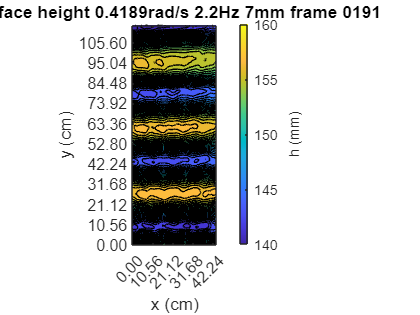

clear 
close all
clc

% Define the base directory for input and output files
input_dir = 'D:\Matlab\Matlab input\20240909_full_plate_final\20240909_0.4189radps_2.2Hz_7mm_full_plate_separate_frames\Results\';
output_dir = 'D:\Matlab\Matlab output\20240909_full_plate_final_results\20240909_0.4189radps_2.2Hz_7mm_full_plate\';

% Define the base file name and extension
base_file_name = '20240909_0.4189radps_2.2Hz_7mm_full_plate_frame_';
file_extension = 'A_vel_new.dat';

% Define the range of frames to process
start_frame = 190;
end_frame = 191;

% Loop over the frames
for frame_num = start_frame:end_frame
    % Construct the file name
    frame_str = sprintf('%04d', frame_num);
    file_name = [base_file_name, frame_str, file_extension];
    input_file = fullfile(input_dir, file_name);
    
    % Load the data
    dr = loadvec(input_file);

    % Copy dr to dr_new & delete rows and columns with only zeros
    dr_new = dr;
    dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
    dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
    dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
    dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vy(all(dr_new.vy == 0, 2), :) = [];

    % Compute the surface height
    h_0 = 150; % surface-pattern distance in mm
    h = surfheight(dr_new, h_0);

    % Plot the surface height & save figure
    contourf(h.w, 25)
    axis equal
    ax = gca;
    numbers_long_axis = (dr_new.x - 63.3601) ./ 10;     % 47.52
    numbers_short_axis = (dr_new.y + 594.001) ./ 10;

    % Determine the positions of the ticks you want to display (e.g., every 10th label)
    x_tick_positions = 1:40:length(numbers_short_axis);
    y_tick_positions = 1:40:length(numbers_long_axis);

    % Set the ticks at these positions
    ax.XTick = x_tick_positions;
    ax.YTick = y_tick_positions;

    % Set the labels at these positions and format them to 2 decimal places
    ax.XTickLabel = arrayfun(@(x) sprintf('%.2f', x), numbers_short_axis(x_tick_positions), 'UniformOutput', false);
    ax.YTickLabel = arrayfun(@(y) sprintf('%.2f', y), numbers_long_axis(y_tick_positions), 'UniformOutput', false);

    % Set the title and labels
    title(sprintf('Surface height 0.4189rad/s 2.2Hz 7mm frame %s', frame_str));
    col = colorbar;
    xlabel('x (cm)');
    ylabel('y (cm)');
    ylabel(col, 'h (mm)');
    caxis([140, 160]);

    % Save the figure
    output_file = fullfile(output_dir, sprintf('20240909_0.4189radps_2.2Hz_7mm_full_plate_surface_height_%s.png', frame_str));
    exportgraphics(gcf, output_file);

    % Close the figure to avoid memory issues
    %close all;
end

% Computing Fourier transform

fourier_t = fft(h.w)

fourier_t = 1.0e+04 *

   6.5309 + 0.0000i   6.5308 + 0.0000i   6.5314 + 0.0000i   6.5312 + 0.0000i   6.5316 + 0.0000i   6.5317 + 0.0000i   6.5323 + 0.0000i   6.5323 + 0.0000i   6.5329 + 0.0000i   6.5330 + 0.0000i   6.5335 + 0.0000i   6.5335 + 0.0000i   6.5341 + 0.0000i   6.5343 + 0.0000i   6.5347 + 0.0000i   6.5347 + 0.0000i   6.5351 + 0.0000i   6.5351 + 0.0000i   6.5355 + 0.0000i   6.5356 + 0.0000i   6.5362 + 0.0000i   6.5362 + 0.0000i   6.5368 + 0.0000i   6.5367 + 0.0000i   6.5374 + 0.0000i   6.5373 + 0.0000i   6.5380 + 0.0000i   6.5377 + 0.0000i   6.5383 + 0.0000i   6.5379 + 0.0000i   6.5384 + 0.0000i   6.5381 + 0.0000i   6.5388 + 0.0000i   6.5386 + 0.0000i   6.5391 + 0.0000i   6.5387 + 0.0000i   6.5391 + 0.0000i   6.5386 + 0.0000i   6.5391 + 0.0000i   6.5387 + 0.0000i   6.5394 + 0.0000i   6.5390 + 0.0000i   6.5396 + 0.0000i   6.5392 + 0.0000i   6.5398 + 0.0000i   6.5396 + 0.0000i   6.5403 + 0.0000i   6.5400 + 0.0000i   6.5407 + 0.0000i   6.5404 + 0.0000i
  -0.0351 + 0.0051i  -0.03

plot

Error using plot
Not enough input arguments.

dr = loadvec('D:\Matlab\Matlab input\20240715_full_plate\20240715_rot_2.6Hz_9mm_full_plate_separate_frames\Results\20240715_rot_2.6Hz_9mm_full_plate_frame_0200A_vel_new.dat');

dr_new=dr;
% Delete zeros for x comp

dr_new.vx(:,all(dr_new.vx == 0,1))=[];
dr_new.vx(all(dr_new.vx == 0,2),:)=[];

dr_new.vy(:,all(dr_new.vy == 0,1))=[];
dr_new.vy(all(dr_new.vy == 0,2),:)=[];

% Compute the surface height

%h_0 = 13/0.15; % 1 pixel is 0.15 mm % 11 mm % surface-pattern distance in mm
h_0 = 150; % 150 surface-pattern distance in mm
h = surfheight(dr_new,h_0);
% Plot the surface height & save figure

%surf(h.w)
%showf(h.w)
%contourf(h.w, 25);
contour3(h.w);
axis equal
ax = gca;

title('Surface height A3 pattern rot 2.6Hz 9mm 2024-07-15 0200')
col = colorbar;
xlabel('x (mm)');
ylabel('y (mm)');
ylabel(col,'h (mm)');
%caxis([85, 95]);
%w=h.w
%exportgraphics(gcf,'C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab\Output\20240618_new_A3_results\20240618_rot_2Hz_5mm_new_A3_frame_surface_height_0160.png')


% to change axes labels
% % Manually format the labels to have a consistent exponent
% x_tick_labels = numbers_short_axis(x_tick_positions) / 1e1;
% y_tick_labels = numbers_long_axis(y_tick_positions) / 1e1;

% ax.XTickLabel = arrayfun(@(x) sprintf('%.2f\\times10^1', x), x_tick_labels, 'UniformOutput', false);
% ax.YTickLabel = arrayfun(@(y) sprintf('%.2f\\times10^1', y), y_tick_labels, 'UniformOutput', false);
% 

% % Set the labels at these positions
% ax.XTickLabel = numbers_short_axis(x_tick_positions);
% ax.YTickLabel = numbers_long_axis(y_tick_positions);
% 
% % Set the tick format to scientific notation
% xtickformat('%0.1e');
% ytickformat('%0.1e');
